fs = 8000;
duration = 0.1;
gap = 0.1

gap = 0.1000


% P = 7, R = 7, M = 6
% PRPM = "7776"

[~,z] = generate_wave({"7","7","7","6"},fs,duration,gap);

#### Plot

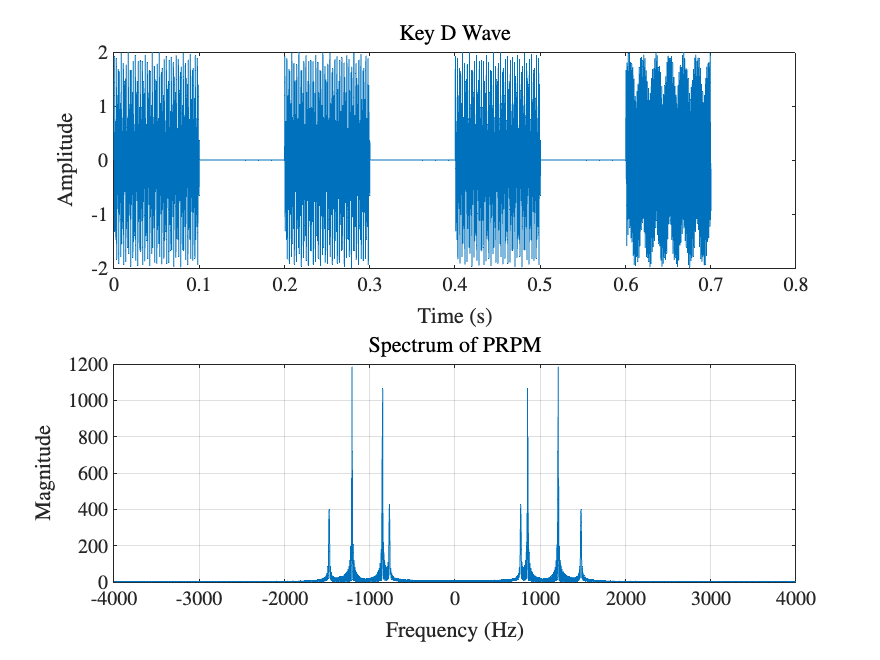

subplot(2,1,1)
plot(t_total, z);
title("Key D Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of PRPM');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
print('TeX/images/4F.eps', '-depsc');